recordFile = "./data/49/H60-L01_to_AUM-AL20.wav";
% recordFile = "./data/49/AUM-AL20_to_H60-L01.wav";
recordFile2 = "./data/49/AUM-AL20_to_H60-L01.wav";
samplingRate = 44100;
fBegin = 2000;
fEnd = 6000;
chirpTimeMs = 100;
device1D = 0.01;
device2D = 0.01;
soundSpeed = 340;

## 原始信号

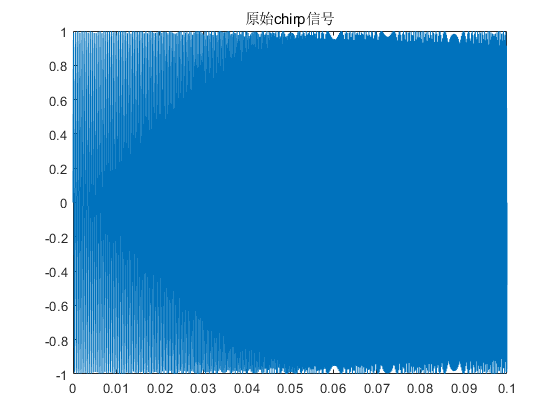

[originChirpT, originChirpY] = generateChirp(samplingRate,fBegin, fEnd, chirpTimeMs, 0);
%% 时域处理
plot(originChirpT, originChirpY);
title("原始chirp信号")

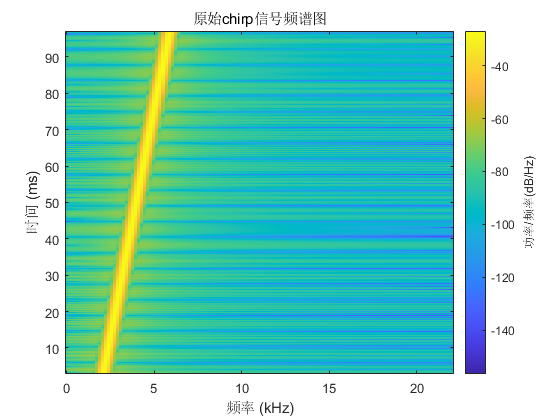

spectrogram(originChirpY, 256, 250, 256, samplingRate);
title("原始chirp信号频谱图")

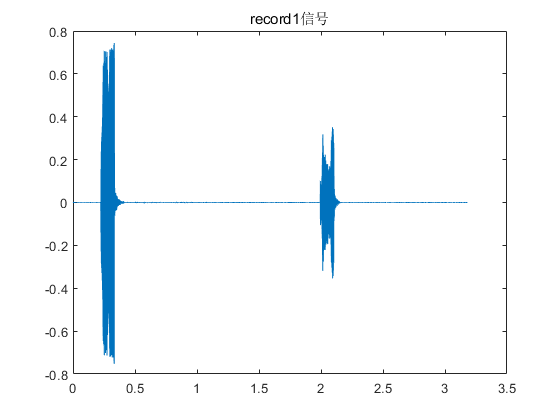



[recordY, recordFs] = audioread(recordFile);
len1 = length(recordY);
%% 时域处理
t1 = (0:len1-1)/recordFs;
plot(t1, recordY);
title("record1信号");

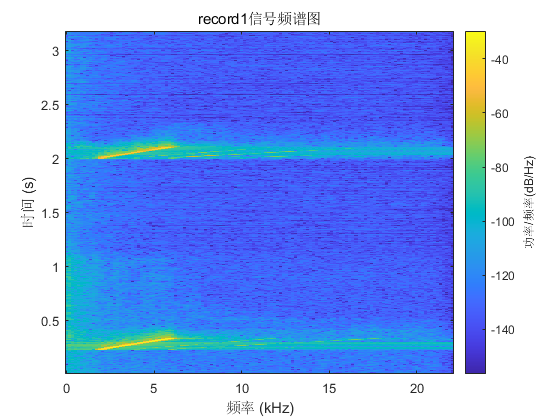

spectrogram(recordY, 256, 250, 256, samplingRate);
title("record1信号频谱图");

## 互相关

[c,lags] = xcorr(recordY, originChirpY)

c = 	1.0e+02 *

   0.000000000000000
                   0
  -0.000000000000000
  -0.000000000000000
                   0
   0.000000000000000
  -0.000000000000000
   0.000000000000000
   0.000000000000000
   0.000000000000000


lags =      -146411     -146410     -146409     -146408     -146407     -146406     -146405     -146404     -146403     -146402     -146401     -146400     -146399     -146398     -146397     -146396     -146395     -146394     -146393     -146392     -146391     -146390     -146389     -146388     -146387     -146386     -146385     -146384     -146383     -146382     -146381     -146380     -146379     -146378     -146377     -146376     -146375     -146374     -146373     -146372     -146371     -146370     -146369     -146368     -146367     -146366     -146365     -146364     -146363     -146362


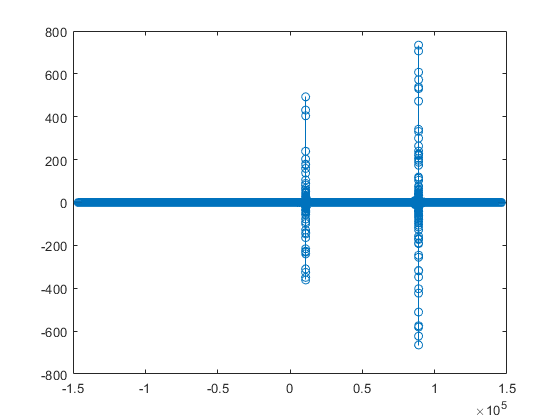

stem(lags, c)

% 原始信号数
stdSampleNum = length(originChirpY);

% 首先找到一个全局最大值
[maxValue, maxIndex] = max(c)

maxValue =      7.341632355494003e+02


maxIndex =       235301


rangeStart1 = maxIndex - stdSampleNum

rangeStart1 =       230890


rangeEnd1 = rangeStart1 + stdSampleNum + stdSampleNum - 1;
peak1 = lags(1, maxIndex)

peak1 =        88889


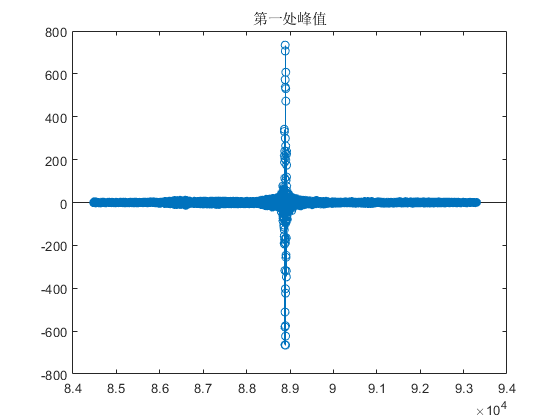

stem(lags(rangeStart1:rangeEnd1), c(rangeStart1:rangeEnd1))
title("第一处峰值")

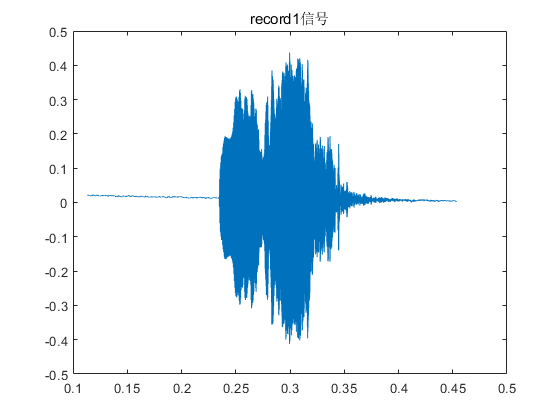


plot(t1(5000:20000), recordY(5000:20000));
title("record1信号");

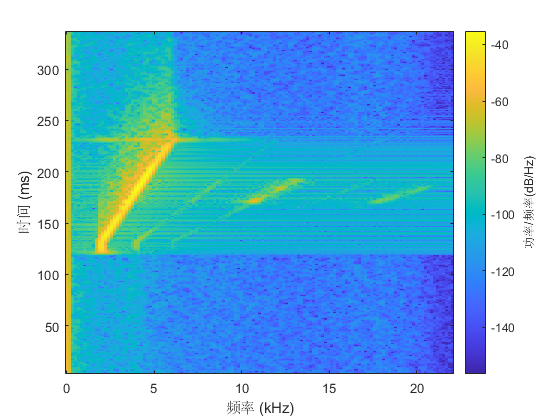

spectrogram(recordY(5000:20000), 256, 250, 256, samplingRate);


% 在其余两段中找另一个全局最大值
tmp = [c(1:rangeStart1 - 1); zeros(stdSampleNum + stdSampleNum, 1); c(rangeEnd1 + 1:length(c))]

tmp = 	1.0e+02 *

   0.000000000000000
                   0
  -0.000000000000000
  -0.000000000000000
                   0
   0.000000000000000
  -0.000000000000000
   0.000000000000000
   0.000000000000000
   0.000000000000000


[maxValue, maxIndex] = max(tmp)

maxValue =      4.929070171098185e+02


maxIndex =       157217


rangeStart2 = maxIndex - stdSampleNum

rangeStart2 =       152806


rangeEnd2 = rangeStart2 + stdSampleNum + stdSampleNum - 1;
peak2 = lags(1, maxIndex)

peak2 =        10805


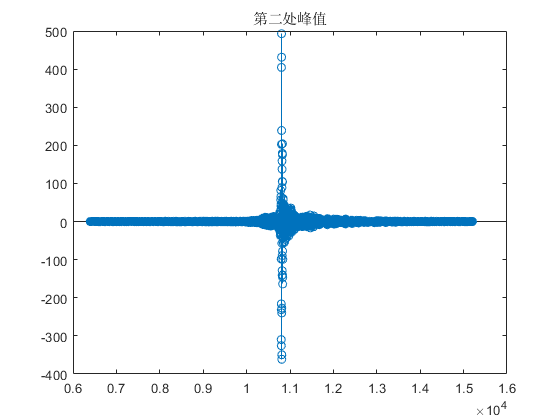

stem(lags(rangeStart2:rangeEnd2), tmp(rangeStart2:rangeEnd2))
title("第二处峰值")


format long
timeDifference = abs(peak1 - peak2) / samplingRate

timeDifference =    1.770612244897959



computeTimeDifference(recordY, originChirpY, samplingRate)

ans =    1.770612244897959


## 计算距离

[recordY, recordFs] = audioread(recordFile);
td1 = computeTimeDifference(recordY, originChirpY, samplingRate)

td1 =    1.770793650793651


[recordY, recordFs] = audioread(recordFile2);
td2 = computeTimeDifference(recordY, originChirpY, samplingRate)

td2 =    1.770612244897959


D = abs(td1 - td2) * soundSpeed / 2 + (device1D + device2D) / 2

D =    0.040839002267591



computeDistance(recordFile, recordFile2, device1D, device2D, samplingRate, fBegin, fEnd, chirpTimeMs, soundSpeed)

ans =    0.040839002267591
